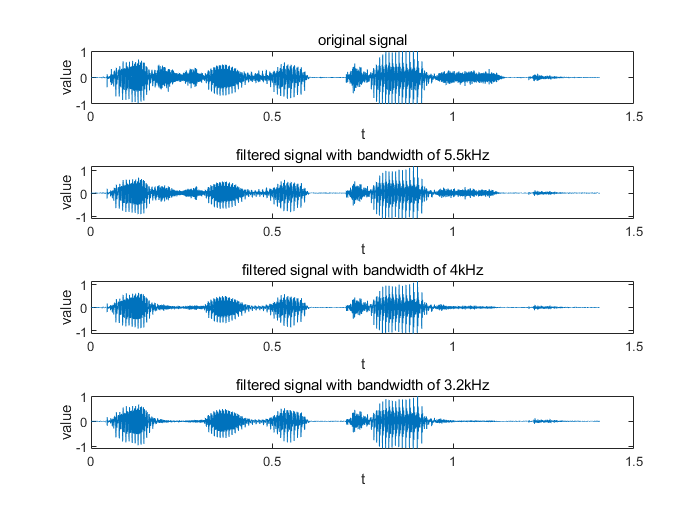

%3.19
[signal,fs]=audioread("test_16k.wav");
t=0:1/fs:(length(signal)-1)/fs;
figure
subplot(4,1,1);
plot(t,signal);
xlabel('t');
ylabel('value');
title('original signal');

cutf1=5500;
[b1,a1]=butter(6,cutf1/(fs/2));
filteredsignalof5500=filter(b1,a1,signal);
subplot(4,1,2);
plot(t,filteredsignalof5500);
xlabel('t');
ylabel('value');
title('filtered signal with bandwidth of 5.5kHz');

cutf2=4000;
[b2,a2]=butter(6,cutf2/(fs/2));
filteredsignalof4000=filter(b2,a2,signal);
subplot(4,1,3);
plot(t,filteredsignalof4000);
xlabel('t');
ylabel('value');
title('filtered signal with bandwidth of 4kHz');

cutf3=3200;
[b3,a3]=butter(6,cutf3/(fs/2));
filteredsignalof3200=filter(b3,a3,signal);
subplot(4,1,4);
plot(t,filteredsignalof3200);
xlabel('t');
ylabel('value');
title('filtered signal with bandwidth of 3.2kHz');

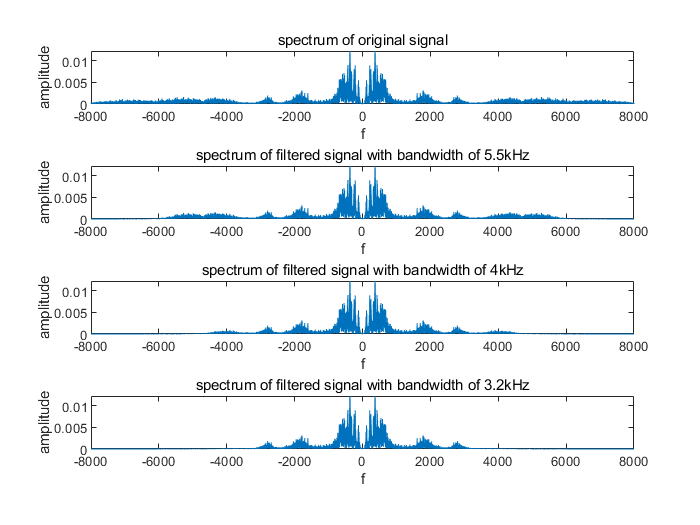


amplitudeoforiginal=fftshift(fft(signal/length(signal)));
f=linspace(-fs/2,fs/2-1,length(signal));
figure
subplot(4,1,1);
plot(f,abs(amplitudeoforiginal));
xlabel('f');
ylabel('amplitude');
title('spectrum of original signal');

amplitudeof5500=fftshift(fft(filteredsignalof5500/length(filteredsignalof5500)));
f=linspace(-fs/2,fs/2-1,length(filteredsignalof5500));
subplot(4,1,2);
plot(f,abs(amplitudeof5500));
xlabel('f');
ylabel('amplitude');
title('spectrum of filtered signal with bandwidth of 5.5kHz');

amplitudeof4000=fftshift(fft(filteredsignalof4000/length(filteredsignalof4000)));
f=linspace(-fs/2,fs/2-1,length(filteredsignalof4000));
subplot(4,1,3);
plot(f,abs(amplitudeof4000));
xlabel('f');
ylabel('amplitude');
title('spectrum of filtered signal with bandwidth of 4kHz');

amplitudeof3200=fftshift(fft(filteredsignalof3200/length(filteredsignalof3200)));
f=linspace(-fs/2,fs/2-1,length(filteredsignalof3200));
subplot(4,1,4);
plot(f,abs(amplitudeof3200));
xlabel('f');
ylabel('amplitude');
title('spectrum of filtered signal with bandwidth of 3.2kHz');

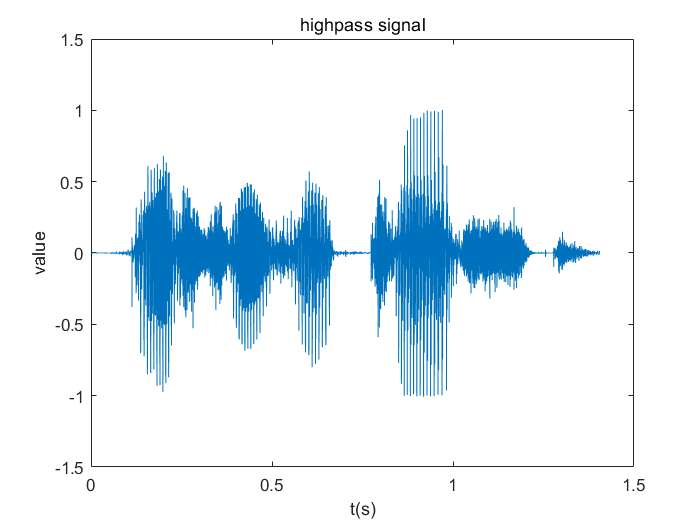



%3.21
Hd = highpass;
HPF_result=filter(Hd,signal);
sound(HPF_result,fs);
figure;
t_highpass=0:1/fs:(length(HPF_result)-1)/fs;
plot(t_highpass,HPF_result);
xlabel('t(s)');
ylabel('value');
title('highpass signal');

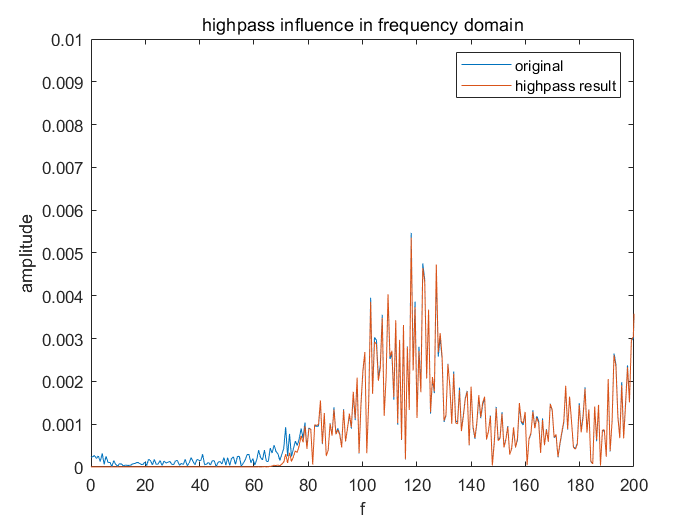


figure
plot(f,abs(amplitudeoforiginal));
xlabel('f');
ylabel('amplitude');
title('highpass influence in frequency domain');
axis([0 200 0 0.01]);
hold on;
amplitudeofHPF=fftshift(fft(HPF_result/length(HPF_result)));
f_hpf=linspace(-fs/2,fs/2-1,length(HPF_result));
plot(f,abs(amplitudeofHPF));
legend('original','highpass result');